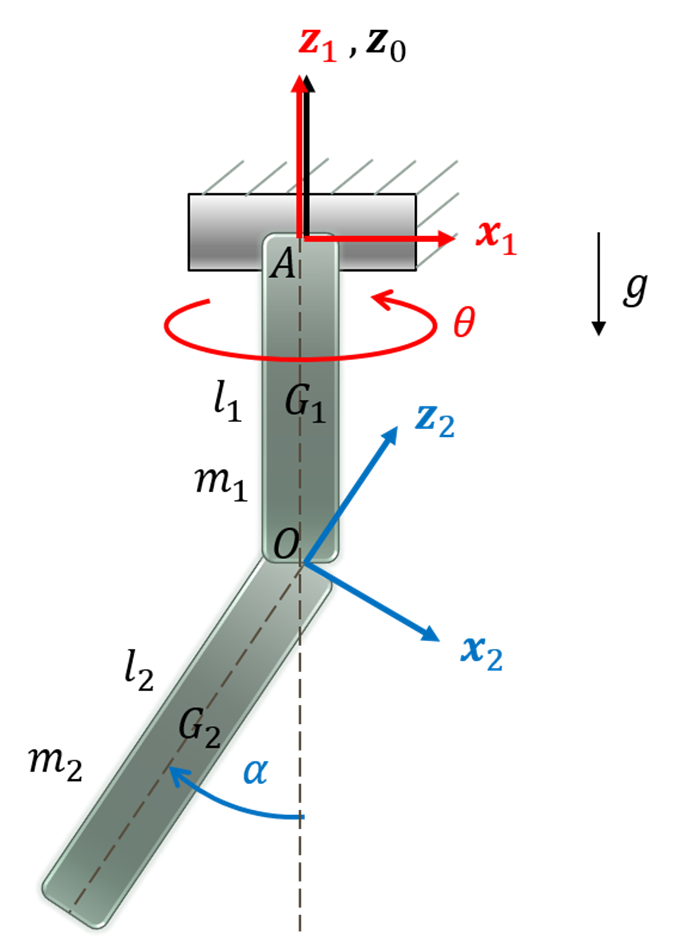

syms t l1 r1 m1 l2 r2 m2 theta(t) alpha(t)

%Creating inertia tensor cylinders

Ixx1 = m1*r1^2/4+ m1*l1^2/12;
Iyy1=Ixx1;
Izz1 = m1*r1^2/2;

I1_1=[Ixx1, 0, 0; 0, Iyy1,0; 0,0,Izz1]

$$I1\_1 = \left(\begin{array}{ccc} \frac{m_{1}\,{l_{1}}^{2}}{12}+\frac{m_{1}\,{r_{1}}^{2}}{4} & 0 & 0\\ 0 & \frac{m_{1}\,{l_{1}}^{2}}{12}+\frac{m_{1}\,{r_{1}}^{2}}{4} & 0\\ 0 & 0 & \frac{m_{1}\,{r_{1}}^{2}}{2} \end{array}\right)$$


Ixx2 = m2*r2^2/4+ m2*l2^2/12;
Iyy2=Ixx2;
Izz2 = m2*r2^2/2;

I2_2=[Ixx2, 0, 0; 0, Iyy2,0; 0,0,Izz2]

$$I2\_2 = \left(\begin{array}{ccc} \frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4} & 0 & 0\\ 0 & \frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4} & 0\\ 0 & 0 & \frac{m_{2}\,{r_{2}}^{2}}{2} \end{array}\right)$$

%Creating rotation matrices

%rotation that brings vectors from frame 1 to frame 0
R01=[cos(theta), -sin(theta), 0;
       sin(theta), cos(theta), 0;
        0 , 0, 1]

$$R01(t) = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & -\sin\left(\theta \left(t\right)\right) & 0\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

    
R10=R01.';

%rotation that brings vectors from frame 2 to frame one
R12= [cos(alpha), 0, sin(alpha);
        0 , 1, 0;
        -sin(alpha) 0 cos(alpha)]

$$R12(t) = \left(\begin{array}{ccc} \cos\left(\alpha \left(t\right)\right) & 0 & \sin\left(\alpha \left(t\right)\right)\\ 0 & 1 & 0\\ -\sin\left(\alpha \left(t\right)\right) & 0 & \cos\left(\alpha \left(t\right)\right) \end{array}\right)$$


R21=(R12.');

## %Kinematics cylinder 1

%_# indicates the frame
w1_1=[0;0;diff(theta,t)]

$$w1\_1(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$


rAG1_1=[0;0;-l1/2]

$$rAG1\_1 = \left(\begin{array}{c} 0\\ 0\\ -\frac{l_{1}}{2} \end{array}\right)$$

rG1O_1=rAG1_1;
rAO_1=[0;0;-l1]

$$rAO\_1 = \left(\begin{array}{c} 0\\ 0\\ -l_{1} \end{array}\right)$$


rAG1_dot_1=diff(rAG1_1,t) + cross(w1_1,rAG1_1)

$$rAG1\_dot\_1(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


rAG1_ddot_1=diff(rAG1_dot_1,t) + cross(w1_1, rAG1_dot_1)

$$rAG1\_ddot\_1(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


rG1O_dot_1=diff(rG1O_1,t) + cross(w1_1, rG1O_1)

$$rG1O\_dot\_1(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


rG1O_ddot_1=diff(rG1O_dot_1,t) + cross(w1_1, rG1O_dot_1)

$$rG1O\_ddot\_1(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


rAO_dot_1=diff(rAO_1,t) + cross(w1_1, rAO_1)

$$rAO\_dot\_1(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


rAO_ddot_1=diff(rAO_dot_1,t) + cross(w1_1, rAO_dot_1)

$$rAO\_ddot\_1(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

%Angular  momentum cylinder 1

h1_1=I1_1*w1_1;

h1_dot_1=diff(h1_1,t)+ cross(w1_1,h1_1)

$$h1\_dot\_1(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{m_{1}\,{r_{1}}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2} \end{array}\right)$$

## Kinematics cylinder 2

w21_2=[0; diff(alpha,t);0]

$$w21\_2(t) = \left(\begin{array}{c} 0\\ \frac{\partial }{\partial t}\alpha \left(t\right)\\ 0 \end{array}\right)$$

w2_2=w21_2+ R21*w1_1

$$w2\_2(t) = \left(\begin{array}{c} -\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\alpha \left(t\right)\\ \cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$


rOG2_2=[0;0;-l2/2]

$$rOG2\_2 = \left(\begin{array}{c} 0\\ 0\\ -\frac{l_{2}}{2} \end{array}\right)$$


rOG2_dot_2=diff(rOG2_2,t) + cross(w2_2,rOG2_2)

$$rOG2\_dot\_2(t) = \left(\begin{array}{c} -\frac{l_{2}\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}\\ -\frac{l_{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}\\ 0 \end{array}\right)$$

rOG2_ddot_2=diff(rOG2_dot_2,t) + cross(w2_2,rOG2_dot_2);
rOG2_ddot_2=simplify(rOG2_ddot_2)

$$rOG2\_ddot\_2(t) = \begin{array}{l} \left(\begin{array}{c} \frac{l_{2}\,\sin\left(2\,\alpha \left(t\right)\right)\,\sigma_{1}}{4}-\frac{l_{2}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{2}\\ -\frac{l_{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}-l_{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\\ \frac{l_{2}\,{\sin\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{1}}{2}+\frac{l_{2}\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$


rAG2_ddot_2=R21*rAO_ddot_1 + rOG2_ddot_2

$$rAG2\_ddot\_2(t) = \begin{array}{l} \left(\begin{array}{c} \frac{l_{2}\,\sin\left(2\,\alpha \left(t\right)\right)\,\sigma_{1}}{4}-\frac{l_{2}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{2}\\ -\frac{l_{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}-l_{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\\ \frac{l_{2}\,{\sin\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{1}}{2}+\frac{l_{2}\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

%Angular  momentum cylinder 2

h2_2=I2_2*w2_2;

h2_dot_2=diff(h2_2,t)+ cross(w2_2,h2_2)

$$h2\_dot\_2(t) = \begin{array}{l} \left(\begin{array}{c} \frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}-2\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)-\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}\,\sigma_{3}\\ \sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)-\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}\,\sigma_{2}+\frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{2}}{2}\\ \frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{3}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

## Kinetics cylinder 2

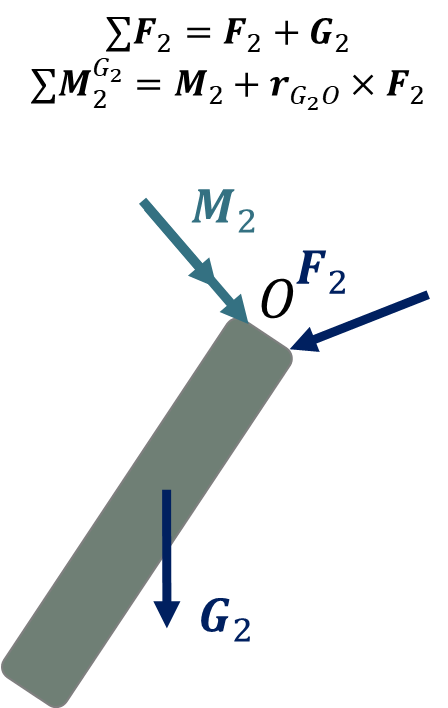

## %Linear NE-eq 2nd link

syms g M2x tau_2 M2z F2x F2y F2z
p2_dot_2=m2*rAG2_ddot_2

$$p2\_dot\_2(t) = \begin{array}{l} \left(\begin{array}{c} -m_{2}\,\left(\frac{l_{2}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{2}-\frac{l_{2}\,\sin\left(2\,\alpha \left(t\right)\right)\,\sigma_{1}}{4}\right)\\ -m_{2}\,\left(\frac{l_{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}+l_{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\right)\\ m_{2}\,\left(\frac{l_{2}\,{\sin\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{1}}{2}+\frac{l_{2}\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$


G2_0=[0;0;-m2*g];
G2_1=G2_0;

%sum F2_2 = F2_2+G2_2 = p2_dot_2

F2_2=p2_dot_2 - R21*G2_1

$$F2\_2(t) = \begin{array}{l} \left(\begin{array}{c} -m_{2}\,\left(\frac{l_{2}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{2}-\frac{l_{2}\,\sin\left(2\,\alpha \left(t\right)\right)\,\sigma_{1}}{4}\right)-g\,m_{2}\,\sin\left(\alpha \left(t\right)\right)\\ -m_{2}\,\left(\frac{l_{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}+l_{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\right)\\ m_{2}\,\left(\frac{l_{2}\,{\sin\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{1}}{2}+\frac{l_{2}\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{2}\right)+g\,m_{2}\,\cos\left(\alpha \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% what NOT to do %%%%%%%%%%%%%%%
F2_2=[F2x;F2y;F2z]

$$F2\_2 = \left(\begin{array}{c} \mathrm{F2x}\\ \mathrm{F2y}\\ \mathrm{F2z} \end{array}\right)$$











%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% The correct way %%%%%%%%%%%%%%%
[F2x,F2y,F2z]=solve([F2x;F2y;F2z]==F2_2, [F2x,F2y,F2z])

$$F2x = 0$$

$$F2y = 0$$

$$F2z = 0$$

## Angular NE-eq 2nd link

%sumM= M2_2+ rOG2_2 x F2_2 = h2_dot_2

M2_2= -cross(rOG2_2,F2_2)+ h2_dot_2

$$M2\_2(t) = \begin{array}{l} \left(\begin{array}{c} \frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}-\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}\,\sigma_{3}-2\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)-\frac{\mathrm{F2y}\,l_{2}}{2}\\ \frac{\mathrm{F2x}\,l_{2}}{2}+\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)-\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}\,\sigma_{2}+\frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{2}}{2}\\ \frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{3}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

M2_2=simplify(M2_2)

$$M2\_2(t) = \begin{array}{l} \left(\begin{array}{c} -\frac{m_{2}\,\sin\left(\alpha \left(t\right)\right)\,{l_{2}}^{2}\,\sigma_{2}}{12}-\frac{m_{2}\,\sin\left(\alpha \left(t\right)\right)\,{r_{2}}^{2}\,\sigma_{2}}{4}-\frac{m_{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,{l_{2}}^{2}\,\frac{\partial }{\partial t}\alpha \left(t\right)}{6}-\frac{\mathrm{F2y}\,l_{2}}{2}\\ \frac{\mathrm{F2x}\,l_{2}}{2}+\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)-\frac{\sigma_{4}\,\sigma_{1}\,\sigma_{3}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,\sigma_{4}\,\sigma_{3}}{4}\\ \frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{2}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{4}=\sin\left(2\,\alpha \left(t\right)\right) \end{array}$$





[M2x,tau_2,M2z]=solve([M2x;tau_2;M2z]==M2_2,[M2x,tau_2,M2z])

$$M2x = -\frac{m_{2}\,\sin\left(\alpha \left(t\right)\right)\,{l_{2}}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{12}-\frac{m_{2}\,\sin\left(\alpha \left(t\right)\right)\,{r_{2}}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{4}-\frac{m_{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,{l_{2}}^{2}\,\frac{\partial }{\partial t}\alpha \left(t\right)}{6}-\frac{\mathrm{F2y}\,l_{2}}{2}$$

$$tau\_2 = \begin{array}{l} \frac{\mathrm{F2x}\,l_{2}}{2}+\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)-\frac{\sin\left(2\,\alpha \left(t\right)\right)\,\sigma_{1}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(2\,\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{4}\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4} \end{array}$$

$$M2z = \frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}$$

M2_2=[M2x;tau_2;M2z] %if we redefine  tau2 than we can't use the equation

$$M2\_2 = \begin{array}{l} \left(\begin{array}{c} -\frac{m_{2}\,\sin\left(\alpha \left(t\right)\right)\,{l_{2}}^{2}\,\sigma_{2}}{12}-\frac{m_{2}\,\sin\left(\alpha \left(t\right)\right)\,{r_{2}}^{2}\,\sigma_{2}}{4}-\frac{m_{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,{l_{2}}^{2}\,\frac{\partial }{\partial t}\alpha \left(t\right)}{6}-\frac{\mathrm{F2y}\,l_{2}}{2}\\ \frac{\mathrm{F2x}\,l_{2}}{2}+\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)-\frac{\sigma_{4}\,\sigma_{1}\,\sigma_{3}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,\sigma_{4}\,\sigma_{3}}{4}\\ \frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{2}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{4}=\sin\left(2\,\alpha \left(t\right)\right) \end{array}$$

tau_2 %this is an equation of motion

$$tau\_2 = \begin{array}{l} \frac{\mathrm{F2x}\,l_{2}}{2}+\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)-\frac{\sin\left(2\,\alpha \left(t\right)\right)\,\sigma_{1}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(2\,\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{4}\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4} \end{array}$$

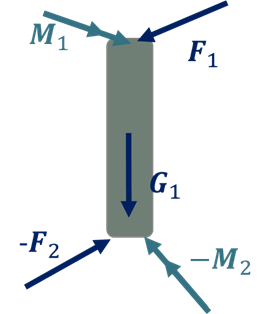

## Linear NE-eq 1st link

syms F1x F1y F1z tau_1 M1x M1y

%sumF = F1-F2+G1 = p1_dot_1
G1_1=[0;0;-m1*g]

$$G1\_1 = \left(\begin{array}{c} 0\\ 0\\ -g\,m_{1} \end{array}\right)$$


p1_dot_1=m1*rAG1_ddot_1

$$p1\_dot\_1(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


F1_1=p1_dot_1 +R12*F2_2 -G1_1

$$F1\_1(t) = \left(\begin{array}{c} \mathrm{F2x}\,\cos\left(\alpha \left(t\right)\right)+\mathrm{F2z}\,\sin\left(\alpha \left(t\right)\right)\\ \mathrm{F2y}\\ g\,m_{1}+\mathrm{F2z}\,\cos\left(\alpha \left(t\right)\right)-\mathrm{F2x}\,\sin\left(\alpha \left(t\right)\right) \end{array}\right)$$

## Angular NE-eq first link

%SumM1=M1-M2+rG1A X F1 - rG1 x F2

%syms M1_1
F2_1=R12*F2_2

$$F2\_1(t) = \left(\begin{array}{c} \mathrm{F2x}\,\cos\left(\alpha \left(t\right)\right)+\mathrm{F2z}\,\sin\left(\alpha \left(t\right)\right)\\ \mathrm{F2y}\\ \mathrm{F2z}\,\cos\left(\alpha \left(t\right)\right)-\mathrm{F2x}\,\sin\left(\alpha \left(t\right)\right) \end{array}\right)$$

M1_1= +R12*M2_2 + cross(rAG1_1,F1_1)+cross(rG1O_1,F2_1)+h1_dot_1

$$M1\_1(t) = \begin{array}{l} \left(\begin{array}{c} \mathrm{F2y}\,l_{1}+\sin\left(\alpha \left(t\right)\right)\,\sigma_{5}-\cos\left(\alpha \left(t\right)\right)\,\sigma_{4}\\ \frac{\mathrm{F2x}\,l_{2}}{2}+\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)-l_{1}\,\left(\mathrm{F2x}\,\cos\left(\alpha \left(t\right)\right)+\mathrm{F2z}\,\sin\left(\alpha \left(t\right)\right)\right)-\frac{\sigma_{3}\,\sigma_{1}\,\sigma_{2}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,\sigma_{3}\,\sigma_{2}}{4}\\ \cos\left(\alpha \left(t\right)\right)\,\sigma_{5}+\sin\left(\alpha \left(t\right)\right)\,\sigma_{4}+\frac{m_{1}\,{r_{1}}^{2}\,\sigma_{6}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=\sin\left(2\,\alpha \left(t\right)\right)\\ \sigma_{4}=\frac{\mathrm{F2y}\,l_{2}}{2}+\frac{{l_{2}}^{2}\,m_{2}\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{6}}{12}+\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{6}}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{6}\\ \sigma_{5}=\frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{6}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}\\ \sigma_{6}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$


[M1x,M1y,tau_1]=solve([M1x;M1y;tau_1]==M1_1,[M1x,M1y,tau_1])

$$M1x = \begin{array}{l} \mathrm{F2y}\,l_{1}+\sin\left(\alpha \left(t\right)\right)\,\left(\frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{1}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}\right)-\cos\left(\alpha \left(t\right)\right)\,\left(\frac{\mathrm{F2y}\,l_{2}}{2}+\frac{{l_{2}}^{2}\,m_{2}\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}}{12}+\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{6}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

$$M1y = \begin{array}{l} \frac{\mathrm{F2x}\,l_{2}}{2}+\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)-l_{1}\,\left(\mathrm{F2x}\,\cos\left(\alpha \left(t\right)\right)+\mathrm{F2z}\,\sin\left(\alpha \left(t\right)\right)\right)-\frac{\sin\left(2\,\alpha \left(t\right)\right)\,\sigma_{1}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(2\,\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{4}\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4} \end{array}$$

$$tau\_1 = \begin{array}{l} \cos\left(\alpha \left(t\right)\right)\,\left(\frac{m_{2}\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{1}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}\right)+\sin\left(\alpha \left(t\right)\right)\,\left(\frac{\mathrm{F2y}\,l_{2}}{2}+\frac{{l_{2}}^{2}\,m_{2}\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}}{12}+\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(\alpha \left(t\right)\right)\,\sigma_{1}}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{6}\right)+\frac{m_{1}\,{r_{1}}^{2}\,\sigma_{1}}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

% Compute simplified symbolic expression
tau_1 = expand(tau_1)

$$tau\_1 = \begin{array}{l} \frac{m_{2}\,{l_{2}}^{2}\,\sigma_{2}\,\sigma_{1}}{12}+\frac{m_{1}\,{r_{1}}^{2}\,\sigma_{1}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,{\cos\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{1}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,\sigma_{2}\,\sigma_{1}}{4}+\frac{m_{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\,{l_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{6}-\frac{m_{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}+\frac{\mathrm{F2y}\,l_{2}\,\sin\left(\alpha \left(t\right)\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{2}={\sin\left(\alpha \left(t\right)\right)}^{2} \end{array}$$


%chosen torque to be applied
tau1 = 10*sin(t)

$$tau1 = 10\,\sin\left(t\right)$$

tau2 = 5*cos(t)

$$tau2 = 5\,\cos\left(t\right)$$


%taus should be part of EOM, change eqs to tau-xxxx
tau_1=tau1-tau_1==0

$$tau\_1 = \begin{array}{l} -\frac{m_{2}\,{l_{2}}^{2}\,\sigma_{2}\,\sigma_{1}}{12}-\frac{m_{1}\,{r_{1}}^{2}\,\sigma_{1}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,{\cos\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{1}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sigma_{2}\,\sigma_{1}}{4}-\frac{m_{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\,{l_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{6}+\frac{m_{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}-\frac{\mathrm{F2y}\,l_{2}\,\sin\left(\alpha \left(t\right)\right)}{2}+10\,\sin\left(t\right)=0\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{2}={\sin\left(\alpha \left(t\right)\right)}^{2} \end{array}$$

tau_2=tau2-tau_2==0

$$tau\_2 = \begin{array}{l} 5\,\cos\left(t\right)-\frac{\mathrm{F2x}\,l_{2}}{2}-\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)+\frac{\sin\left(2\,\alpha \left(t\right)\right)\,\sigma_{1}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sin\left(2\,\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{4}=0\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4} \end{array}$$

## Isolating EOM using matrix

eqns=[tau_1,tau_2]

$$eqns = \begin{array}{l} \left(\begin{array}{cc} -\frac{m_{2}\,{l_{2}}^{2}\,\sigma_{5}\,\sigma_{2}}{12}-\frac{m_{1}\,{r_{1}}^{2}\,\sigma_{2}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,{\cos\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{2}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sigma_{5}\,\sigma_{2}}{4}-\frac{m_{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\,{l_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{6}+\frac{m_{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\,{r_{2}}^{2}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}-\frac{\mathrm{F2y}\,l_{2}\,\sin\left(\alpha \left(t\right)\right)}{2}+10\,\sin\left(t\right)=0 & 5\,\cos\left(t\right)-\frac{\mathrm{F2x}\,l_{2}}{2}-\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)+\frac{\sigma_{4}\,\sigma_{1}\,\sigma_{3}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,\sigma_{4}\,\sigma_{3}}{4}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{4}=\sin\left(2\,\alpha \left(t\right)\right)\\ \sigma_{5}={\sin\left(\alpha \left(t\right)\right)}^{2} \end{array}$$


syms theta_new alpha_new theta_ddot theta_dot alpha_dot alpha_ddot 

old_syms=[diff(theta,t,2), diff(theta,t), theta, diff(alpha,t,2), diff(alpha,t), alpha]

$$old\_syms(t) = \left(\begin{array}{cccccc} \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) & \frac{\partial }{\partial t}\theta \left(t\right) & \theta \left(t\right) & \frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right) & \frac{\partial }{\partial t}\alpha \left(t\right) & \alpha \left(t\right) \end{array}\right)$$

new_syms = [theta_ddot , theta_dot, theta_new, alpha_ddot, alpha_dot, alpha_new]

$$new\_syms = \left(\begin{array}{cccccc} \ddot{\theta } & \dot{\theta } & \theta_{\mathrm{new}} & \ddot{\alpha } & \dot{\alpha } & \alpha_{\mathrm{new}} \end{array}\right)$$


eqns_new=subs(eqns, old_syms, new_syms)

$$eqns\_new = \begin{array}{l} \left(\begin{array}{cc} -\frac{\dot{\alpha }\,m_{2}\,\dot{\theta }\,{l_{2}}^{2}\,\cos\left(\alpha_{\mathrm{new}}\right)\,\sin\left(\alpha_{\mathrm{new}}\right)}{6}-\frac{m_{2}\,\ddot{\theta }\,{l_{2}}^{2}\,{\sin\left(\alpha_{\mathrm{new}}\right)}^{2}}{12}-\frac{\mathrm{F2y}\,l_{2}\,\sin\left(\alpha_{\mathrm{new}}\right)}{2}-\frac{m_{1}\,\ddot{\theta }\,{r_{1}}^{2}}{2}-\frac{m_{2}\,\ddot{\theta }\,{r_{2}}^{2}\,{\cos\left(\alpha_{\mathrm{new}}\right)}^{2}}{2}+\frac{\dot{\alpha }\,m_{2}\,\dot{\theta }\,{r_{2}}^{2}\,\cos\left(\alpha_{\mathrm{new}}\right)\,\sin\left(\alpha_{\mathrm{new}}\right)}{2}-\frac{m_{2}\,\ddot{\theta }\,{r_{2}}^{2}\,{\sin\left(\alpha_{\mathrm{new}}\right)}^{2}}{4}+10\,\sin\left(t\right)=0 & 5\,\cos\left(t\right)-\frac{\mathrm{F2x}\,l_{2}}{2}-\ddot{\alpha }\,\sigma_{1}+\frac{{\dot{\theta }}^{2}\,\sin\left(2\,\alpha_{\mathrm{new}}\right)\,\sigma_{1}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,{\dot{\theta }}^{2}\,\sin\left(2\,\alpha_{\mathrm{new}}\right)}{4}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4} \end{array}$$


[A,b]=equationsToMatrix(eqns_new,[alpha_ddot,theta_ddot ]) %A*X=b, where X=[alpha_ddot, theta_ddot ]

$$A = \left(\begin{array}{cc} 0 & -\frac{m_{2}\,{l_{2}}^{2}\,{\sin\left(\alpha_{\mathrm{new}}\right)}^{2}}{12}-\frac{m_{1}\,{r_{1}}^{2}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,{\cos\left(\alpha_{\mathrm{new}}\right)}^{2}}{2}-\frac{m_{2}\,{r_{2}}^{2}\,{\sin\left(\alpha_{\mathrm{new}}\right)}^{2}}{4}\\ -\frac{m_{2}\,{l_{2}}^{2}}{12}-\frac{m_{2}\,{r_{2}}^{2}}{4} & 0 \end{array}\right)$$

$$b = \left(\begin{array}{c} \frac{\dot{\alpha }\,m_{2}\,\dot{\theta }\,\cos\left(\alpha_{\mathrm{new}}\right)\,\sin\left(\alpha_{\mathrm{new}}\right)\,{l_{2}}^{2}}{6}+\frac{\mathrm{F2y}\,\sin\left(\alpha_{\mathrm{new}}\right)\,l_{2}}{2}-\frac{\dot{\alpha }\,m_{2}\,\dot{\theta }\,\cos\left(\alpha_{\mathrm{new}}\right)\,\sin\left(\alpha_{\mathrm{new}}\right)\,{r_{2}}^{2}}{2}-10\,\sin\left(t\right)\\ \frac{\mathrm{F2x}\,l_{2}}{2}-5\,\cos\left(t\right)-\frac{{\dot{\theta }}^{2}\,\sin\left(2\,\alpha_{\mathrm{new}}\right)\,\left(\frac{m_{2}\,{l_{2}}^{2}}{12}+\frac{m_{2}\,{r_{2}}^{2}}{4}\right)}{2}+\frac{m_{2}\,{r_{2}}^{2}\,{\dot{\theta }}^{2}\,\sin\left(2\,\alpha_{\mathrm{new}}\right)}{4} \end{array}\right)$$


X_ddotNew=A\b

$$X\_ddotNew = \left(\begin{array}{c} \frac{m_{2}\,\sin\left(2\,\alpha_{\mathrm{new}}\right)\,{l_{2}}^{2}\,{\dot{\theta }}^{2}-12\,\mathrm{F2x}\,l_{2}-3\,m_{2}\,\sin\left(2\,\alpha_{\mathrm{new}}\right)\,{r_{2}}^{2}\,{\dot{\theta }}^{2}+120\,\cos\left(t\right)}{2\,\left(m_{2}\,{l_{2}}^{2}+3\,m_{2}\,{r_{2}}^{2}\right)}\\ \frac{2\,\left(-\dot{\alpha }\,m_{2}\,\dot{\theta }\,\cos\left(\alpha_{\mathrm{new}}\right)\,\sin\left(\alpha_{\mathrm{new}}\right)\,{l_{2}}^{2}-3\,\mathrm{F2y}\,\sin\left(\alpha_{\mathrm{new}}\right)\,l_{2}+3\,\dot{\alpha }\,m_{2}\,\dot{\theta }\,\cos\left(\alpha_{\mathrm{new}}\right)\,\sin\left(\alpha_{\mathrm{new}}\right)\,{r_{2}}^{2}+60\,\sin\left(t\right)\right)}{m_{2}\,{l_{2}}^{2}\,{\sin\left(\alpha_{\mathrm{new}}\right)}^{2}+6\,m_{1}\,{r_{1}}^{2}+6\,m_{2}\,{r_{2}}^{2}\,{\cos\left(\alpha_{\mathrm{new}}\right)}^{2}+3\,m_{2}\,{r_{2}}^{2}\,{\sin\left(\alpha_{\mathrm{new}}\right)}^{2}} \end{array}\right)$$

X_ddotNew=simplify(X_ddotNew)

$$X\_ddotNew = \left(\begin{array}{c} \frac{m_{2}\,\sin\left(2\,\alpha_{\mathrm{new}}\right)\,{l_{2}}^{2}\,{\dot{\theta }}^{2}-12\,\mathrm{F2x}\,l_{2}-3\,m_{2}\,\sin\left(2\,\alpha_{\mathrm{new}}\right)\,{r_{2}}^{2}\,{\dot{\theta }}^{2}+120\,\cos\left(t\right)}{2\,m_{2}\,\left({l_{2}}^{2}+3\,{r_{2}}^{2}\right)}\\ \frac{-\dot{\alpha }\,m_{2}\,\dot{\theta }\,\sin\left(2\,\alpha_{\mathrm{new}}\right)\,{l_{2}}^{2}-6\,\mathrm{F2y}\,\sin\left(\alpha_{\mathrm{new}}\right)\,l_{2}+3\,\dot{\alpha }\,m_{2}\,\dot{\theta }\,\sin\left(2\,\alpha_{\mathrm{new}}\right)\,{r_{2}}^{2}+120\,\sin\left(t\right)}{m_{2}\,{l_{2}}^{2}\,{\sin\left(\alpha_{\mathrm{new}}\right)}^{2}+6\,m_{1}\,{r_{1}}^{2}-3\,m_{2}\,{r_{2}}^{2}\,{\sin\left(\alpha_{\mathrm{new}}\right)}^{2}+6\,m_{2}\,{r_{2}}^{2}} \end{array}\right)$$

Finding EOMs

%syms t l1 r1 m1 l2 r2 m2 theta(t) alpha(t)
%add numerical values 

l1_num=0.5 %m

l1_num = 0.5000

l2_num=0.5 %m

l2_num = 0.5000

r1_num=0.01 %m

r1_num = 0.0100

r2_num =0.01 %m

r2_num = 0.0100

m1_num=1.18 % kg

m1_num = 1.1800

m2_num =1.18 %kg

m2_num = 1.1800


% %chosen torque to be applied
% tau1 = 10*sin(t)
% tau2 = 5*cos(t)

g_num=9.8 %m/s^2

g_num = 9.8000


sym_measuments= [l1 r1 m1 l2 r2 m2 g ]

$$sym\_measuments = \left(\begin{array}{ccccccc} l_{1} & r_{1} & m_{1} & l_{2} & r_{2} & m_{2} & g \end{array}\right)$$

numerical_meas=[ l1_num r1_num m1_num l2_num r2_num m2_num g_num]

numerical_meas =     0.5000    0.0100    1.1800    0.5000    0.0100    1.1800    9.8000



tau_1=subs(tau_1, sym_measuments, numerical_meas)

$$tau\_1 = \begin{array}{l} -\frac{59\,{\cos\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{1}}{1000000}-\frac{147677\,{\sin\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{1}}{6000000}-\frac{59\,\sigma_{1}}{1000000}-\frac{147323\,\frac{\partial }{\partial t}\theta \left(t\right)\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{3000000}-\frac{\mathrm{F2y}\,\sin\left(\alpha \left(t\right)\right)}{4}+10\,\sin\left(t\right)=0\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

tau_2=subs(tau_2, sym_measuments, numerical_meas)

$$tau\_2 = -\frac{147677\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{6000000}+\frac{147323\,\sin\left(2\,\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{12000000}-\frac{\mathrm{F2x}}{4}+5\,\cos\left(t\right)=0$$


%not used
Xdot_num=subs(X_ddotNew,sym_measuments, numerical_meas)

$$Xdot\_num = \left(\begin{array}{c} \frac{2497\,\sin\left(2\,\alpha_{\mathrm{new}}\right)\,{\dot{\theta }}^{2}}{5006}-\frac{1500000\,\mathrm{F2x}}{147677}+\frac{30000000\,\cos\left(t\right)}{147677}\\ -\frac{3\,\mathrm{F2y}\,\sin\left(\alpha_{\mathrm{new}}\right)-120\,\sin\left(t\right)+\frac{147323\,\dot{\alpha }\,\dot{\theta }\,\sin\left(2\,\alpha_{\mathrm{new}}\right)}{500000}}{\frac{147323\,{\sin\left(\alpha_{\mathrm{new}}\right)}^{2}}{500000}+\frac{177}{125000}} \end{array}\right)$$

## Numerical solution

%his approach may cause S to be different order for different runs
[X_dot,S] = odeToVectorField(tau_1,tau_2)

$$X\_dot = \left(\begin{array}{c} Y_{2}\\ \frac{2497\,\sin\left(2\,Y_{1}\right)\,{Y_{4}}^{2}}{5006}-\frac{1500000\,\mathrm{F2x}}{147677}+\frac{30000000\,\cos\left(t\right)}{147677}\\ Y_{4}\\ -\frac{2\,\left(750000\,\mathrm{F2y}\,\sin\left(Y_{1}\right)-30000000\,\sin\left(t\right)+147323\,\cos\left(Y_{1}\right)\,\sin\left(Y_{1}\right)\,Y_{2}\,Y_{4}\right)}{59\,\left(6\,{\cos\left(Y_{1}\right)}^{2}+2503\,{\sin\left(Y_{1}\right)}^{2}+6\right)} \end{array}\right)$$

$$S = \left(\begin{array}{c} \alpha \\ \mathrm{Dalpha}\\ \theta \\ \mathrm{Dtheta} \end{array}\right)$$

eom = matlabFunction(X_dot,'Vars',{'t','Y'})

Error using sym/matlabFunction>checkVarsSubset
Free variables 'F2x,F2y' must be included in 'Vars' value.

Error in sym/matlabFunction>checkVars (line 251)
checkVarsSubset(vexpanded,funvars);

Error in sym/matlabFunction (


options = odeset('RelTol',1e-7,'AbsTol',1e-7'); % solver options
alpha0=pi/3;
alpha_dot0=0;
theta0=0;
theta_dot0=10;
x_init = [alpha0; alpha_dot0; theta0; theta_dot0];   % initial condition

tspan=[0 7]
EOM_Solved = ode45(eom,tspan,x_init,options);



Plotting

%% EVAULATE THE SOLUTION
    dt = 0.03;                                  % set time step     
    t = tspan(1):dt:tspan(2);                   % creat time vector
    X_ddotNew = deval(EOM_Solved,t);                           % deval


%% PLOT THE STATES
    plot(t,X_ddotNew)
    xlabel('time')
    ylabel('states')
    h = legend('$\alpha$','$\dot{\alpha}$','$\theta$','$\dot{\theta}$');
    set(h,'Interpreter','latex')

%you can pass the solved EOM to a function for the animation.
%function Animation(EOM_Solved,t,R10,R21)
%The animation should use the numerical values of theta,alpha in the
%rotation

%The initial conditions were just random numbers, they might not make
%physical sense